clear; close all; clc

## Variáveis Iniciais

syms l1 l2 q1 q2 q3 dq1 dq2 dq3 ddq1 ddq2 ddq3;
syms dp_x dp_y dp_z ddp_x ddp_y ddp_z;
syms w_x w_y w_z alpha_x alpha_y alpha_z;

## Cinematica Direta - Posição (Jacobiano Angular Incluso)

q = [q1; q2; q3];
P_1 = [0 0 l1];
P_2 = [l2 0 0];
P_3 = [q3 0 0];
[JA_1_0, JA_2_0, JA_3_0, T_1_0, T_2_0, T_3_0, P_1_0, P_2_0, P_3_0] = cinematicaDiretaEsferico(P_1,P_2,P_3,q)

$$JA\_1\_0 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 1 & 0 & 0 \end{array}\right)$$

$$JA\_2\_0 = \left(\begin{array}{ccc} 0 & -\sin\left(q_{1}\right) & 0\\ 0 & \cos\left(q_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

$$JA\_3\_0 = \left(\begin{array}{ccc} 0 & -\sin\left(q_{1}\right) & 0\\ 0 & \cos\left(q_{1}\right) & 0\\ 1 & 0 & 0 \end{array}\right)$$

$$T\_1\_0 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & \bar{l_{1}}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T\_2\_0 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \bar{l_{2}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \bar{l_{2}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & \bar{l_{1}}-\bar{l_{2}}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$T\_3\_0 = \left(\begin{array}{cccc} \cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\sin\left(q_{1}\right) & \cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \bar{l_{2}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\bar{q_{3}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{1}\right) & \sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \bar{l_{2}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+\bar{q_{3}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ -\sin\left(q_{2}\right) & 0 & \cos\left(q_{2}\right) & \bar{l_{1}}-\bar{l_{2}}\,\sin\left(q_{2}\right)-\bar{q_{3}}\,\sin\left(q_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

$$P\_1\_0 = \left(\begin{array}{c} 0\\ 0\\ \bar{l_{1}} \end{array}\right)$$

$$P\_2\_0 = \left(\begin{array}{c} \bar{l_{2}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \bar{l_{2}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \bar{l_{1}}-\bar{l_{2}}\,\sin\left(q_{2}\right) \end{array}\right)$$

$$P\_3\_0 = \left(\begin{array}{c} \bar{l_{2}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\bar{q_{3}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \bar{l_{2}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+\bar{q_{3}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \bar{l_{1}}-\bar{l_{2}}\,\sin\left(q_{2}\right)-\bar{q_{3}}\,\sin\left(q_{2}\right) \end{array}\right)$$

## Jacobiano Linear

JL_1_0 = jacobian(P_1_0,q)

$$JL\_1\_0 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

JL_2_0 = jacobian(P_2_0,q)

$$JL\_2\_0 = \left(\begin{array}{ccc} -\bar{l_{2}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\bar{l_{2}}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ \bar{l_{2}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\bar{l_{2}}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & 0\\ 0 & -\bar{l_{2}}\,\cos\left(q_{2}\right) & 0 \end{array}\right)$$

JL_3_0 = jacobian(P_3_0,q)

$$JL\_3\_0 = \left(\begin{array}{ccc} -\bar{l_{2}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-\bar{q_{3}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & -\bar{l_{2}}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-\bar{q_{3}}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\\ \bar{l_{2}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\bar{q_{3}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & -\bar{l_{2}}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)-\bar{q_{3}}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & \cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ 0 & -\bar{l_{2}}\,\cos\left(q_{2}\right)-\bar{q_{3}}\,\cos\left(q_{2}\right) & -\sin\left(q_{2}\right) \end{array}\right)$$

## Cálculo das Singularidades

det_JL_1_0 = simplify(det(JL_1_0))

$$det\_JL\_1\_0 = 0$$

sing_JL_1_0 = solve(det_JL_1_0==0,q)

sing_JL_1_0 = struct with fields:
    q1: 0
    q2: 0
    q3: 0



det_JL_2_0 = simplify(det(JL_2_0))

$$det\_JL\_2\_0 = 0$$

sing_JL_2_0 = solve(det_JL_2_0==0,q)

sing_JL_2_0 = struct with fields:
    q1: 0
    q2: 0
    q3: 0



det_JL_3_0 = simplify(det(JL_3_0))

$$det\_JL\_3\_0 = -\cos\left(q_{2}\right)\,{\left(\bar{l_{2}}+\bar{q_{3}}\right)}^{2}$$

% o resultado é um struct com os campos q1, q2 e q3. Para acessar os valores é
% só fazer sing_JL_3_0.q1, etc...
sing_JL_3_0 = solve(det_JL_3_0==0,q) 

sing_JL_3_0 = struct with fields:
    q1: [2×1 sym]
    q2: [2×1 sym]
    q3: [2×1 sym]


## Cinemática Direta - Velocidade Linear

dq = [dq1; dq2; dq3];
v_1_0 = simplify(JL_1_0*dq)

$$v\_1\_0 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$

v_2_0 = simplify(JL_2_0*dq)

$$v\_2\_0 = \left(\begin{array}{c} -\bar{l_{2}}\,\left({\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ \bar{l_{2}}\,\left({\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ -{\mathrm{dq}}_{2}\,\bar{l_{2}}\,\cos\left(q_{2}\right) \end{array}\right)$$

v_3_0 = simplify(JL_3_0*dq)

$$v\_3\_0 = \left(\begin{array}{c} {\mathrm{dq}}_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\left(\bar{l_{2}}+\bar{q_{3}}\right)-{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(\bar{l_{2}}+\bar{q_{3}}\right)\\ {\mathrm{dq}}_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\left(\bar{l_{2}}+\bar{q_{3}}\right)-{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\left(\bar{l_{2}}+\bar{q_{3}}\right)\\ -{\mathrm{dq}}_{2}\,\left(\bar{l_{2}}\,\cos\left(q_{2}\right)+\bar{q_{3}}\,\cos\left(q_{2}\right)\right)-{\mathrm{dq}}_{3}\,\sin\left(q_{2}\right) \end{array}\right)$$

## Cinemática Direta - Velocidade Angular

w_1_0 = simplify(JA_1_0*dq);
w_2_0 = simplify(JA_2_0*dq);
w_3_0 = simplify(JA_3_0*dq);

## Cinemática Direta - Aceleração Linear

ddq = [ddq1; ddq2; ddq3];
dJL_1_0 = [jacobian(JL_1_0(:,1),q)*dq jacobian(JL_1_0(:,2),q)*dq jacobian(JL_1_0(:,3),q)*dq]

$$dJL\_1\_0 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

a_1_0 = simplify(dJL_1_0*dq + JL_1_0*ddq)

$$a\_1\_0 = \left(\begin{array}{c} 0\\ 0\\ 0 \end{array}\right)$$


dJL_2_0 = [jacobian(JL_2_0(:,1),q)*dq jacobian(JL_2_0(:,2),q)*dq jacobian(JL_2_0(:,3),q)*dq]

$$dJL\_2\_0 = \left(\begin{array}{ccc} {\mathrm{dq}}_{2}\,\bar{l_{2}}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)-{\mathrm{dq}}_{1}\,\bar{l_{2}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & {\mathrm{dq}}_{1}\,\bar{l_{2}}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)-{\mathrm{dq}}_{2}\,\bar{l_{2}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) & 0\\ -{\mathrm{dq}}_{1}\,\bar{l_{2}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-{\mathrm{dq}}_{2}\,\bar{l_{2}}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -{\mathrm{dq}}_{1}\,\bar{l_{2}}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)-{\mathrm{dq}}_{2}\,\bar{l_{2}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & 0\\ 0 & {\mathrm{dq}}_{2}\,\bar{l_{2}}\,\sin\left(q_{2}\right) & 0 \end{array}\right)$$

a_2_0 = simplify(dJL_2_0*dq + JL_2_0*ddq)

$$a\_2\_0 = \left(\begin{array}{c} -\bar{l_{2}}\,\left(\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,{{\mathrm{dq}}_{1}}^{2}-2\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}+\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,{{\mathrm{dq}}_{2}}^{2}+{\mathrm{ddq}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+{\mathrm{ddq}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ -\bar{l_{2}}\,\left(\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,{{\mathrm{dq}}_{1}}^{2}+2\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,{{\mathrm{dq}}_{2}}^{2}-{\mathrm{ddq}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+{\mathrm{ddq}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\right)\\ \bar{l_{2}}\,\left({{\mathrm{dq}}_{2}}^{2}\,\sin\left(q_{2}\right)-{\mathrm{ddq}}_{2}\,\cos\left(q_{2}\right)\right) \end{array}\right)$$


dJL_3_0 = [jacobian(JL_3_0(:,1),q)*dq jacobian(JL_3_0(:,2),q)*dq jacobian(JL_3_0(:,3),q)*dq]

$$dJL\_3\_0 = \begin{array}{l} \left(\begin{array}{ccc} {\mathrm{dq}}_{2}\,\sigma_{1}-{\mathrm{dq}}_{1}\,\sigma_{4}-{\mathrm{dq}}_{3}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) & {\mathrm{dq}}_{1}\,\sigma_{1}-{\mathrm{dq}}_{2}\,\sigma_{4}-{\mathrm{dq}}_{3}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right) & -{\mathrm{dq}}_{1}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)-{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ {\mathrm{dq}}_{3}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\mathrm{dq}}_{2}\,\sigma_{3}-{\mathrm{dq}}_{1}\,\sigma_{2} & -{\mathrm{dq}}_{1}\,\sigma_{3}-{\mathrm{dq}}_{2}\,\sigma_{2}-{\mathrm{dq}}_{3}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right) & {\mathrm{dq}}_{1}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)-{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ 0 & {\mathrm{dq}}_{2}\,\left(\bar{l_{2}}\,\sin\left(q_{2}\right)+\bar{q_{3}}\,\sin\left(q_{2}\right)\right)-{\mathrm{dq}}_{3}\,\cos\left(q_{2}\right) & -{\mathrm{dq}}_{2}\,\cos\left(q_{2}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\bar{l_{2}}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)+\bar{q_{3}}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{2}=\bar{l_{2}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)+\bar{q_{3}}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\\ \sigma_{3}=\bar{l_{2}}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+\bar{q_{3}}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\\ \sigma_{4}=\bar{l_{2}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+\bar{q_{3}}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right) \end{array}$$

a_3_0 = simplify(dJL_3_0*dq + JL_3_0*ddq)

## Cinemática Direta - Aceleração Angular

dJA_1_0 = [jacobian(JA_1_0(:,1),q)*dq jacobian(JA_1_0(:,2),q)*dq jacobian(JA_1_0(:,3),q)*dq]

$$dJA\_1\_0 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

alpha_1_0 = simplify(dJA_1_0*dq + JA_1_0*ddq)

$$alpha\_1\_0 = \left(\begin{array}{c} 0\\ 0\\ {\mathrm{ddq}}_{1} \end{array}\right)$$


dJA_2_0 = [jacobian(JA_2_0(:,1),q)*dq jacobian(JA_2_0(:,2),q)*dq jacobian(JA_2_0(:,3),q)*dq]

$$dJA\_2\_0 = \left(\begin{array}{ccc} 0 & -{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right) & 0\\ 0 & -{\mathrm{dq}}_{1}\,\sin\left(q_{1}\right) & 0\\ 0 & 0 & 0 \end{array}\right)$$

alpha_2_0 = simplify(dJA_2_0*dq + JA_2_0*ddq)

$$alpha\_2\_0 = \left(\begin{array}{c} -{\mathrm{ddq}}_{2}\,\sin\left(q_{1}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\\ {\mathrm{ddq}}_{2}\,\cos\left(q_{1}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\\ {\mathrm{ddq}}_{1} \end{array}\right)$$


dJA_3_0 = [jacobian(JA_3_0(:,1),q)*dq jacobian(JA_3_0(:,2),q)*dq jacobian(JA_3_0(:,3),q)*dq]

$$dJA\_3\_0 = \left(\begin{array}{ccc} 0 & -{\mathrm{dq}}_{1}\,\cos\left(q_{1}\right) & 0\\ 0 & -{\mathrm{dq}}_{1}\,\sin\left(q_{1}\right) & 0\\ 0 & 0 & 0 \end{array}\right)$$

alpha_3_0 = simplify(dJA_3_0*dq + JA_3_0*ddq)

$$alpha\_3\_0 = \left(\begin{array}{c} -{\mathrm{ddq}}_{2}\,\sin\left(q_{1}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\cos\left(q_{1}\right)\\ {\mathrm{ddq}}_{2}\,\cos\left(q_{1}\right)-{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\sin\left(q_{1}\right)\\ {\mathrm{ddq}}_{1} \end{array}\right)$$

## Cinemática Inversa - Velocidade Linear

dp = [dp_x; dp_y; dp_z];
dq_1_0 = JL_1_0\dp % O operador "\" faz INV(A)*b de maneira mais acurada.

$$dq\_1\_0 = \left(\begin{array}{c} \infty \\ \infty \\ \infty \end{array}\right)$$

dq_2_0 = JL_2_0\dp

$$dq\_2\_0 = \left(\begin{array}{c} \infty \\ \infty \\ \infty \end{array}\right)$$

dq_3_0 = JL_3_0\dp

$$dq\_3\_0 = \begin{array}{l} \left(\begin{array}{c} \frac{{\mathrm{dp}}_{y}\,\cos\left(q_{1}\right)-{\mathrm{dp}}_{x}\,\sin\left(q_{1}\right)}{\left(\bar{l_{2}}\,\cos\left(q_{2}\right)+\bar{q_{3}}\,\cos\left(q_{2}\right)\right)\,\sigma_{2}}\\ -\frac{{\mathrm{dp}}_{z}\,\cos\left(q_{2}\right)\,{\cos\left(q_{1}\right)}^{2}+{\mathrm{dp}}_{x}\,\sin\left(q_{2}\right)\,\cos\left(q_{1}\right)+{\mathrm{dp}}_{z}\,\cos\left(q_{2}\right)\,{\sin\left(q_{1}\right)}^{2}+{\mathrm{dp}}_{y}\,\sin\left(q_{2}\right)\,\sin\left(q_{1}\right)}{\sigma_{1}\,\left(\bar{l_{2}}\,{\cos\left(q_{1}\right)}^{2}+\bar{q_{3}}\,{\cos\left(q_{1}\right)}^{2}+\bar{l_{2}}\,{\sin\left(q_{1}\right)}^{2}+\bar{q_{3}}\,{\sin\left(q_{1}\right)}^{2}\right)}\\ \frac{-{\mathrm{dp}}_{z}\,\sin\left(q_{2}\right)\,{\cos\left(q_{1}\right)}^{2}+{\mathrm{dp}}_{x}\,\cos\left(q_{2}\right)\,\cos\left(q_{1}\right)-{\mathrm{dp}}_{z}\,\sin\left(q_{2}\right)\,{\sin\left(q_{1}\right)}^{2}+{\mathrm{dp}}_{y}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)}{\sigma_{2}\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\cos\left(q_{2}\right)}^{2}+{\sin\left(q_{2}\right)}^{2}\\ \sigma_{2}={\cos\left(q_{1}\right)}^{2}+{\sin\left(q_{1}\right)}^{2} \end{array}$$

## Cinemática Inversa - Velocidade Angular

% w = [w_x; w_y; w_z]; % Simbólico da velocidade angular (rad/s)
% dq_1_0_A = JA_1_0\w % O operador "\" faz INV(A)*b de maneira mais acurada.
% dq_2_0_A = JA_2_0\w
% dq_3_0_A = JA_3_0\w

## Cinemática Inversa - Aceleração Linear

ddp = [ddp_x; ddp_y; ddp_z];
ddq_1_0 = simplify(JL_1_0\(ddp - dJL_1_0*dq))

$$ddq\_1\_0 = \left(\begin{array}{c} \infty \\ \infty \\ \infty \end{array}\right)$$

ddq_2_0 = simplify(JL_2_0\(ddp - dJL_2_0*dq))

$$ddq\_2\_0 = \left(\begin{array}{c} \infty \\ \infty \\ \infty \end{array}\right)$$

ddq_3_0 = simplify(JL_3_0\(ddp - dJL_3_0*dq))

$$ddq\_3\_0 = \left(\begin{array}{c} \frac{{\mathrm{ddp}}_{y}\,\cos\left(q_{1}\right)-{\mathrm{ddp}}_{x}\,\sin\left(q_{1}\right)-2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{3}\,\cos\left(q_{2}\right)+2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\bar{l_{2}}\,\sin\left(q_{2}\right)+2\,{\mathrm{dq}}_{1}\,{\mathrm{dq}}_{2}\,\bar{q_{3}}\,\sin\left(q_{2}\right)}{\cos\left(q_{2}\right)\,\left(\bar{l_{2}}+\bar{q_{3}}\right)}\\ -\frac{2\,{\mathrm{dq}}_{2}\,{\mathrm{dq}}_{3}+{\mathrm{ddp}}_{z}\,\cos\left(q_{2}\right)+\frac{{{\mathrm{dq}}_{1}}^{2}\,\sin\left(2\,q_{2}\right)\,\bar{l_{2}}}{2}+\frac{{{\mathrm{dq}}_{1}}^{2}\,\sin\left(2\,q_{2}\right)\,\bar{q_{3}}}{2}+{\mathrm{ddp}}_{x}\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)+{\mathrm{ddp}}_{y}\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)}{\bar{l_{2}}+\bar{q_{3}}}\\ {{\mathrm{dq}}_{2}}^{2}\,\bar{l_{2}}-{\mathrm{ddp}}_{z}\,\sin\left(q_{2}\right)+{{\mathrm{dq}}_{2}}^{2}\,\bar{q_{3}}+{{\mathrm{dq}}_{1}}^{2}\,\bar{l_{2}}\,{\cos\left(q_{2}\right)}^{2}+{{\mathrm{dq}}_{1}}^{2}\,\bar{q_{3}}\,{\cos\left(q_{2}\right)}^{2}+{\mathrm{ddp}}_{x}\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)+{\mathrm{ddp}}_{y}\,\cos\left(q_{2}\right)\,\sin\left(q_{1}\right) \end{array}\right)$$

## Cinemática Inversa - Posição

% % Variaveis de teste
% l1 = 10;
% posicaoEfetuador_desejada = [3.5355 7 10]';
% 
% % Cálculo da Cinematica Inversa
% elos_inv = cinematicaInversaEsferico(l1,posicaoEfetuador_desejada)

% % Conferindo a resposta
% q1 = 1.1031;
% q2 = 0;
% q3 = 7.8422;
% T_3_0_new = eval(subs(T_3_0))


## Simulação para estudo e validação das equações cinemáticas encontradas

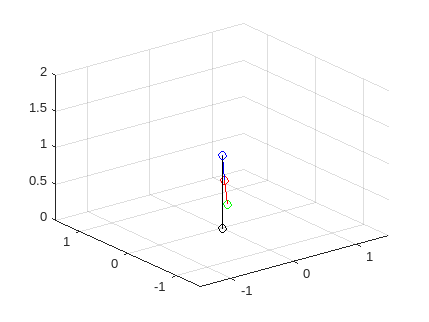

Q1 = linspace(-pi/4,pi/4,100);
% figure(1), plot(Q1,'k*'), grid on, ylabel('q1(t) [rad]')

Q2 = linspace(-pi/3,pi/3,100);
% figure(2), plot(Q2,'k*'), grid on, ylabel('q2(t) [rad]')

Q3 = linspace(0.1,0.5,100);
% figure(3), plot(Q3,'k*'), grid on, ylabel('q3(t) [m]')

x0 = zeros(100,1);
y0 = zeros(100,1);
z0 = zeros(100,1);
x1 = zeros(100,1);
y1 = zeros(100,1);
z1 = zeros(100,1);
x2 = zeros(100,1);
y2 = zeros(100,1);
z2 = zeros(100,1);
x3 = zeros(100,1);
y3 = zeros(100,1);
z3 = zeros(100,1);


l1 = 1;
l2 = 0.5;
figure(7),

for n = 1:1:length(Q1)
    q1 = Q1(n);
    q2 = Q2(n);
    q3 = Q3(n);
    
    x1(n) = eval(subs(P_1_0(1)));
    y1(n) = eval(subs(P_1_0(2)));
    z1(n) = eval(subs(P_1_0(3)));
    x2(n) = eval(subs(P_2_0(1)));
    y2(n) = eval(subs(P_2_0(2)));
    z2(n) = eval(subs(P_2_0(3)));
    x3(n) = eval(subs(P_3_0(1)));
    y3(n) = eval(subs(P_3_0(2)));
    z3(n) = eval(subs(P_3_0(3)));
    
    
    h1 = plot3(x0(n),y0(n),z0(n),'ko'); grid on, hold on
    h2 = plot3(x1(n),y1(n),z1(n),'bo'); 
    h3 = plot3(x2(n),y2(n),z2(n),'ro'); 
    h4 = plot3(x3(n),y3(n),z3(n),'go');

    h5 = line([x0(n) x1(n)],[y0(n) y1(n)],[z0(n) z1(n)]);
    h5.Color = 'k';
    h6 = line([x1(n) x2(n)],[y1(n) y2(n)],[z1(n) z2(n)]);
    h6.Color = 'b';
    h7 = line([x2(n) x3(n)],[y2(n) y3(n)],[z2(n) z3(n)]);
    h7.Color = 'r';
    
    if n == 1
        axis([-1.5 1.5 -1.5 1.5 0 2])
    end
    
    pause(0.05)
    
    if n < length(Q1)
        set(h1,'Visible','off')
        set(h2,'Visible','off')
        set(h3,'Visible','off')
        set(h4,'Visible','off')
        set(h5,'Visible','off')
        set(h6,'Visible','off')
        set(h7,'Visible','off')
    end
    
end

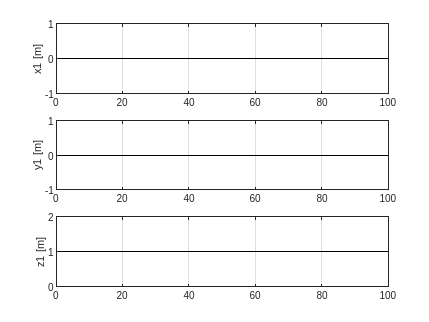


figure(4), 
subplot(3,1,1), plot(x1,'k'), grid on, ylabel('x1 [m]')
subplot(3,1,2), plot(y1,'k'), grid on, ylabel('y1 [m]')
subplot(3,1,3), plot(z1,'k'), grid on, ylabel('z1 [m]')

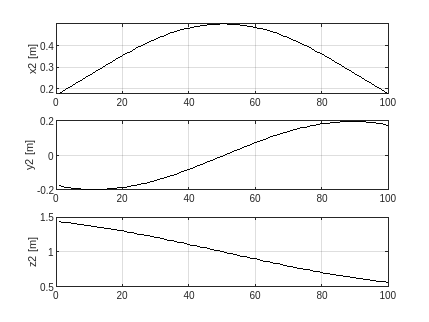


figure(5), 
subplot(3,1,1), plot(x2,'k'), grid on, ylabel('x2 [m]')
subplot(3,1,2), plot(y2,'k'), grid on, ylabel('y2 [m]')
subplot(3,1,3), plot(z2,'k'), grid on, ylabel('z2 [m]')

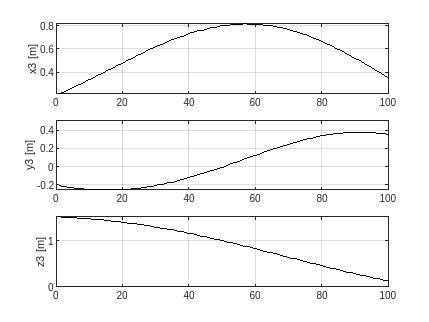


figure(6), 
subplot(3,1,1), plot(x3,'k'), grid on, ylabel('x3 [m]')
subplot(3,1,2), plot(y3,'k'), grid on, ylabel('y3 [m]')
subplot(3,1,3), plot(z3,'k'), grid on, ylabel('z3 [m]')